Envelope Solver

%load case 1
case_loads = linspace(400/6, 400/6, 6);

%{
%load case 2A
lightest = 135 
lightest = lightest / 2
heaviest = lightest
loco = heaviest * 1.35


%load case 2B

lightest = 135 
lightest = lightest / 2
heaviest = lightest * 1.1
loco = heaviest * 1.35
case_loads = [heaviest heaviest lightest lightest loco loco]
%}

steps = 20560 + 1

steps = 20561

x = [linspace(-856, 1200, steps); zeros(1,steps); zeros(1,steps)];
%x is location of leftmost wheel

for j = 1:length(x(1,:))

% calculate location of loads
first = x(1,j);
loads = [case_loads; first + [0 176 340 516 680 856]];

% remove loads not on bridge
i_list = [];
for i = 1:length(loads(1,:))
    if loads(2,i) < 0 || loads(2,i) > 1200
        i_list = [i i_list];
    end
end

for i = i_list
    loads(:,i) = [];
end

% reaction forces
By = sum(loads(2,:).*loads(1,:))/1200;
Ay = sum(loads(1,:)) - By;
V = max(Ay, By);
x(2,j) = V;

% sfd/bmd
SFD = [Ay zeros(1, length(loads(1,:))); loads(2,1) zeros(1, length(loads(1,:))-1) 1200-loads(2, end)];
for i = 1:(length(loads(1,:)))
    SFD(1, i+1) = SFD(1, i) - loads(1, i);
end
for i = 1:length(loads(1,:))-1
    SFD(2, i+1) = loads(2,i+1) - loads(2,i);
end
SFD = [SFD;SFD(1,:).*SFD(2,:)];
BMD = zeros(1,length(SFD(1,:))+1);
for i = 2:length(SFD(1,:))+1
    BMD(i) = BMD(i-1) + SFD(3,i-1);
end
M = max(BMD);
x(3,j) = M;
end
%{
[V xvmax] = max(x(2,:));
V
xvmax = x(1, xvmax)

xvmax = find(x(2,:)==V)
%}
V = max(x(2,:))

V = 257.3333

M = max(x(3,:))

M = 6.9445e+04

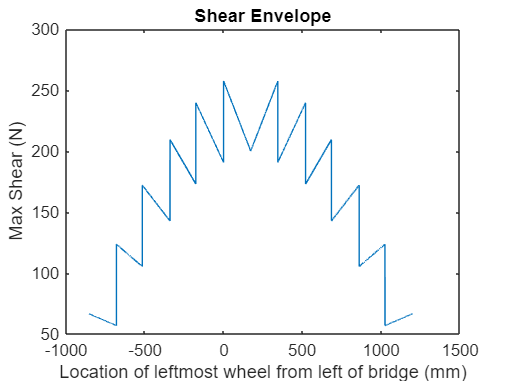

plot(x(1,:), x(2,:))
title("Shear Envelope")
xlabel("Location of leftmost wheel from left of bridge (mm)")
ylabel("Max Shear (N)")

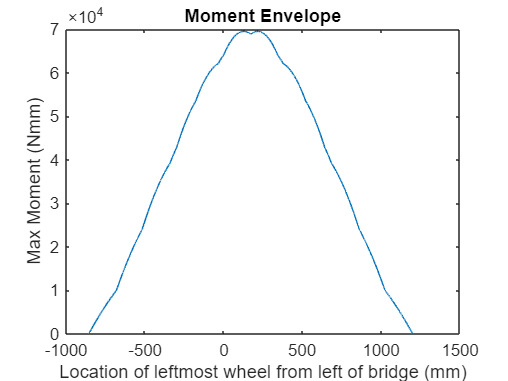

%text(sprintf("Max Shear on Bridge = %f", V))
plot(x(1,:), x(3,:))
title("Moment Envelope")
xlabel("Location of leftmost wheel from left of bridge (mm)")
ylabel("Max Moment (Nmm)")

Geometry Calculator

 
%{
%design 0
b  = [100 5 5 1.27 1.27 80]
h = [1.27 1.27 1.27 73.73 73.73 1.27]
y_knot = [ 75.635 74.365 74.365 38.135 38.135 0.635] 
%}

%design 1
%design 2 - section b 

b = [100 80 5 5 1.27 1.27 80];
h = [1.27 1.27 1.27 1.27 73.73 73.73 1.27];
y_knot = [76.905 75.635 74.365 74.365 38.135 38.135 0.635];


A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)

y_bar = 48.2900

I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

I = 5.2353e+05


%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

Q_cent = 7.6496e+03


b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_1 = 3.6341e+03


b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_2 = 6.4124e+03

Set Variables

%load case 1
%V_max = 772/3;
%M_max = 69445;
V_max = V

V_max = 257.3333

M_max = M

M_max = 6.9445e+04

%y_bar = 41.4;
%I = 418000;
%Q_cent = 6187;
%Q_glue = 4348;
h_total = 75 + 1.27 + 1.27;

b_cent = 2*1.27;
b_glue = 2*(5+1.27);

safe_tens = 30;
safe_comp = 6;
safe_shear_cent = 4;
safe_shear_glue = 2;

E = 4000;
poisson = 0.2;
E_mod = E / (1 - poisson^2);


t1 = 1.27*2;
b1 = 80 - 1.27;
t2 = 1.27;
b2 = 10 + 1.27 / 2;
t3 = 1.27;
b3 = 75 - y_bar;
t4 = 1.27;
b4 = 75 - 1.27;
a4 = 400;

y_b1 = 75 - y_bar +  1.27;
y_b2 = 75 - y_bar + 1.27 + 1.27/2;
y_b3 = 75 - y_bar;

Calculations

tens_stress = M_max * y_bar / I

tens_stress = 6.4056

comp_stress = M_max * (h_total - y_bar) / I

comp_stress = 3.8800

fos_tens =  safe_tens / tens_stress

fos_tens = 4.6834

fos_comp =  safe_comp / comp_stress

fos_comp = 1.5464


%stress_b1 = M_max * y_b1 / I
%stress_b2 = M_max * y_b2 / I
stress_b1 = comp_stress

stress_b1 = 3.8800

stress_b2 = comp_stress

stress_b2 = 3.8800

stress_b3 = M_max * y_b3 / I

stress_b3 = 3.5431


shear_cent = (V_max * Q_cent) / (I * b_cent)

shear_cent = 1.4803

shear_glue_1 = (V_max * Q_glue_1) / (I * b_glue)

shear_glue_1 = 0.1424

shear_glue_2 = (V_max * Q_glue_2) / (I * b_glue)

shear_glue_2 = 0.2514

fos_cent = safe_shear_cent / shear_cent

fos_cent = 2.7021

fos_glue_1 = safe_shear_glue / shear_glue_1

fos_glue_1 = 14.0401

fos_glue_2 = safe_shear_glue / shear_glue_2

fos_glue_2 = 7.9570


buck_1 = 4 * pi^2 * E_mod / 12 * (t1 / b1)^2

buck_1 = 14.2677

buck_2 = 0.425 * pi^2 * E_mod / 12 * (t2 / b2)^2

buck_2 = 20.7696

buck_3 = 6 * pi^2 * E_mod / 12 * (t3 / b3)^2

buck_3 = 46.4855

buck_4 = 5 * pi^2 * E_mod / 12 * ((t4 / b4)^2 + (t4 / a4)^2)

buck_4 = 5.2566

%need to add diaphragms?
fos_b1 = buck_1 / stress_b1

fos_b1 = 3.6772

fos_b2 = buck_2 / stress_b2

fos_b2 = 5.3530

fos_b3 = buck_3 / stress_b3

fos_b3 = 13.1201

fos_b4 = buck_4 / shear_cent

fos_b4 = 3.5510


buck_diaphragm = 4 * pi^2 * E_mod / 12 * ((75 - 1.27*2) / (80 - 1.27*2))^2

buck_diaphragm = 1.1995e+04

Geometry Calc 2

%design 2 - section A
b  = [100 80 5 5 1.27 1.27 80 67.46];
h = [1.27 1.27 1.27 1.27 73.73 73.73 1.27  1.27];
y_knot = [76.905 75.635 74.365 74.365 (73.73/2)+1.27 (73.73/2)+1.27 1.27/2  74.365];


A = b.*h;
y_bar = sum(y_knot.*A)/sum(A)

y_bar = 51.9174

I_knot = b.*(h.^3)/12;
d = y_knot - y_bar;
I = sum(I_knot) + sum(A.*(d.^2))

I = 5.7368e+05


%Q
b = [80 1.27 1.27];
h = [1.27 (y_bar - 1.27) (y_bar - 1.27)];
A = b.*h;
y_knot = [0.635 ((y_bar - 1.27)/2 + 1.27) ((y_bar - 1.27)/2 + 1.27)];
Q_cent = abs(sum(A.*(y_knot - y_bar)))

Q_cent = 8.4681e+03


b = [100];
h = [1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2)];
Q_glue_1 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_1 = 3.1734e+03


b = [100 80];
h = [1.27 1.27];
A = b.*h;
y_knot = [(75 + 1.27 + 1.27/2) (75 + 1.27/2)];
Q_glue_2 = abs(sum(A.*(y_knot - y_bar)))

Q_glue_2 = 5.5831e+03

Calculations 2

tens_stress = M_max * y_bar / I

tens_stress = 6.2847

comp_stress = M_max * (h_total - y_bar) / I

comp_stress = 3.1017

fos_tens =  safe_tens / tens_stress

fos_tens = 4.7735

fos_comp =  safe_comp / comp_stress

fos_comp = 1.9345


y_b3 = 75 - y_bar;
t1 = 1.27*3;
b1 = 75 + 1.27/2

b1 = 75.6350

%stress_b1 = M_max * y_b1 / I
%stress_b2 = M_max * y_b2 / I
stress_b1 = comp_stress

stress_b1 = 3.1017

stress_b2 = comp_stress

stress_b2 = 3.1017

stress_b3 = M_max * y_b3 / I

stress_b3 = 2.7942


shear_cent = (V_max * Q_cent) / (I * b_cent)

shear_cent = 1.4955

shear_glue_1 = (V_max * Q_glue_1) / (I * b_glue)

shear_glue_1 = 0.1135

shear_glue_2 = (V_max * Q_glue_2) / (I * b_glue)

shear_glue_2 = 0.1997

fos_cent = safe_shear_cent / shear_cent

fos_cent = 2.6748

fos_glue_1 = safe_shear_glue / shear_glue_1

fos_glue_1 = 17.6188

fos_glue_2 = safe_shear_glue / shear_glue_2

fos_glue_2 = 10.0144


buck_1 = 4 * pi^2 * E_mod / 12 * (t1 / b1)^2

buck_1 = 34.7834

buck_2 = 0.425 * pi^2 * E_mod / 12 * (t2 / b2)^2

buck_2 = 20.7696

buck_3 = 6 * pi^2 * E_mod / 12 * (t3 / b3)^2

buck_3 = 46.4855

buck_4 = 5 * pi^2 * E_mod / 12 * ((t4 / b4)^2 + (t4 / a4)^2)

buck_4 = 5.2566


fos_b1 = buck_1 / stress_b1

fos_b1 = 11.2145

fos_b2 = buck_2 / stress_b2

fos_b2 = 6.6963

fos_b3 = buck_3 / stress_b3

fos_b3 = 16.6365

fos_b4 = buck_4 / shear_cent

fos_b4 = 3.5151

%need to clarify diaphragm spacing.
buck_diaphragm = 4 * pi^2 * E_mod / 12 * ((75 - 1.27*2) / (80 - 1.27*2))^2

buck_diaphragm = 1.1995e+04